We write the equations governing the system using Lagrange method:

- the Kinetic Energy  $E_c$

- the Dissipation Function  $D$

- the Potential  $V$

- the Torque Lagrangian  $L_{\mathrm{Cm}}$

syms M_R J_R M_T J_T B R g l x(t) x_dot(t) beta(t) beta_dot(t) Cm(t) K_x K_beta

Ec = 0.5*M_R*x_dot^2 + 0.5*M_T*((x_dot + l*beta_dot*cos(beta))^2 + (l*beta_dot*sin(beta))^2) + 0.5*J_R*(x_dot/R)^2 + 0.5*J_T*beta_dot^2

$$Ec(t) = \frac{M_{T}\,\left({\left(\dot{x}\left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\dot{\beta }\left(t\right)\right)}^{2}+l^{2}\,{\sin\left(\beta \left(t\right)\right)}^{2}\,{\dot{\beta }\left(t\right)}^{2}\right)}{2}+\frac{J_{T}\,{\dot{\beta }\left(t\right)}^{2}}{2}+\frac{M_{R}\,{\dot{x}\left(t\right)}^{2}}{2}+\frac{J_{R}\,{\dot{x}\left(t\right)}^{2}}{2\,R^{2}}$$


D = 0.5*B*(x_dot/R - beta_dot)^2

$$D(t) = \frac{B\,{\left(\dot{\beta }\left(t\right)-\frac{\dot{x}\left(t\right)}{R}\right)}^{2}}{2}$$


V = M_T*g*l*cos(beta)

$$V(t) = M_{T}\,g\,l\,\cos\left(\beta \left(t\right)\right)$$


L_Cm = Cm*(x/R - beta)

$$L\_Cm(t) = -\mathrm{Cm}\left(t\right)\,\left(\beta \left(t\right)-\frac{x\left(t\right)}{R}\right)$$

The lagrangian with respect to the $x$ coordinate is

Ec_tmp = diff(Ec,x_dot,1);
Ec_tmp = subs(Ec_tmp,[x_dot,beta_dot],[diff(x,t,1),diff(beta,t,1)]);
fx = diff(Ec_tmp,t,1) - diff(Ec,x,1) + diff(D,x_dot,1) + diff(V,x,1);
lagrange_x = fx == diff(L_Cm,x,1);
lagrange_x = subs(lagrange_x,[x_dot,beta_dot],[diff(x,t,1),diff(beta,t,1)]);
lagrange_x

$$lagrange\_x(t) = \begin{array}{l} M_{R}\,\sigma_{1}+\frac{M_{T}\,\left(-2\,l\,\sin\left(\beta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}+2\,l\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)+2\,\sigma_{1}\right)}{2}-\frac{B\,\left(\frac{\partial }{\partial t}\beta \left(t\right)-\frac{\frac{\partial }{\partial t}x\left(t\right)}{R}\right)}{R}+\frac{J_{R}\,\sigma_{1}}{R^{2}}=\frac{\mathrm{Cm}\left(t\right)}{R}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right) \end{array}$$

The lagrangian with respect to the $\beta$ coordinate is

Ec_tmp = diff(Ec,beta_dot,1);
Ec_tmp = subs(Ec_tmp,[x_dot,beta_dot],[diff(x,t,1),diff(beta,t,1)]);
fbeta = diff(Ec_tmp,t,1) - diff(Ec,beta,1) + diff(D,beta_dot,1) + diff(V,beta,1);
lagrange_beta = fbeta == diff(L_Cm,beta,1);
lagrange_beta = subs(lagrange_beta,[x_dot,beta_dot],[diff(x,t,1),diff(beta,t,1)]);
lagrange_beta

$$lagrange\_beta(t) = \begin{array}{l} \frac{M_{T}\,\left(2\,l\,\cos\left(\beta \left(t\right)\right)\,\left(l\,\cos\left(\beta \left(t\right)\right)\,\sigma_{3}-l\,\sin\left(\beta \left(t\right)\right)\,\sigma_{2}+\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\right)+2\,l^{2}\,{\sin\left(\beta \left(t\right)\right)}^{2}\,\sigma_{3}-\sigma_{1}+4\,l^{2}\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sigma_{2}\right)}{2}+\frac{M_{T}\,\left(\sigma_{1}-2\,l^{2}\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sigma_{2}\right)}{2}+J_{T}\,\sigma_{3}+\frac{B\,\left(2\,\frac{\partial }{\partial t}\beta \left(t\right)-\frac{2\,\frac{\partial }{\partial t}x\left(t\right)}{R}\right)}{2}-M_{T}\,g\,l\,\sin\left(\beta \left(t\right)\right)=-\mathrm{Cm}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=2\,l\,\sin\left(\beta \left(t\right)\right)\,\left(\frac{\partial }{\partial t}x\left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right) \end{array}$$

We now define the control equation

% For now we just leave 0 torque to simulate natural behaviour
control = Cm == -K_x*x + K_beta*beta

$$control(t) = \mathrm{Cm}\left(t\right)=K_{\beta }\,\beta \left(t\right)-K_{x}\,x\left(t\right)$$

control

$$control(t) = \mathrm{Cm}\left(t\right)=K_{\beta }\,\beta \left(t\right)-K_{x}\,x\left(t\right)$$

We define parameters values

params = [M_R J_R M_T J_T B R g l K_x K_beta]

$$params = \left(\begin{array}{cccccccccc} M_{R} & J_{R} & M_{T} & J_{T} & B & R & g & l & K_{x} & K_{\beta } \end{array}\right)$$


kx = -5

kx = -5

kbeta = 10

kbeta = 10


params_val = [2*0.2,...              % M_R    [kg]
              2*0.5*0.2*0.05^2,...   % J_R    [kg*m]
              1,...                  % M_T    [kg]
              0.5*1*0.05^2,...       % J_T    [kg*m]
              0,...                  % B      [N/(rad/s)]
              0.05,...               % R      [m]
              9.81,...               % g      [N/kg]
              0.05,...               % l      [m]
              kx,...                 % K_x    [N*m/m]
              kbeta ...              % K_beta [N*m/rad] 
             ];

lagrange_x = subs(lagrange_x, params, params_val);
lagrange_beta = subs(lagrange_beta, params, params_val);
control = subs(control, params, params_val);

We simulate the dynamics until the robot falls down

eqns = [lagrange_x lagrange_beta control];
vars = [x(t) beta(t) Cm(t)];

[eqns,vars] = reduceDifferentialOrder(eqns,vars);
isLowIndexDAE(eqns,vars)

ans = logical
   1


f = daeFunction(eqns,vars);

opt = odeset('RelTol', 10.0^(-3),'AbsTol',10.0^(-3), 'Events', @(t,y,yp) stop(t,y,yp));



vars

$$vars = \left(\begin{array}{c} x\left(t\right)\\ \beta \left(t\right)\\ \mathrm{Cm}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ {\mathrm{Dbeta}}_{t}\left(t\right) \end{array}\right)$$


ti=0;
tf=3;
timespan = [ti tf];

y0 = [0;+0.1;0;0;0];
yp0 = [0;0;0;0;0];

[y0,yp0] = decic(f,ti,y0,[1 1 0 0 0],yp0,[]);

y0

y0 =          0
    0.1000
    1.0000
         0
         0


yp0

yp0 =          0
         0
         0
   34.6998
 -713.9615


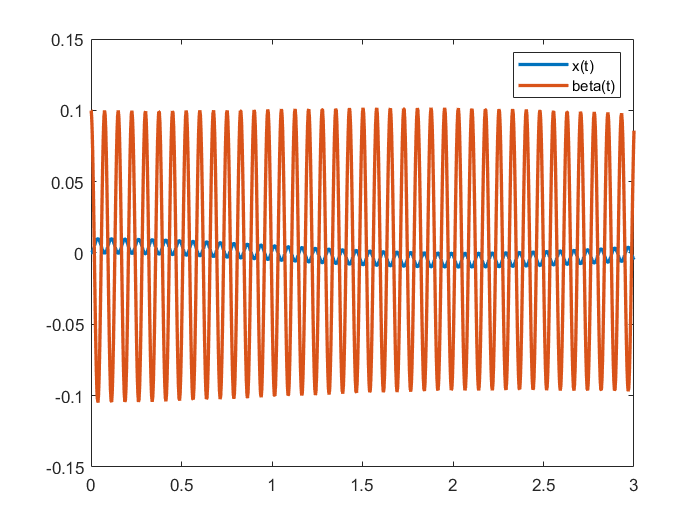


[tSol, ySol] = ode15i(f,timespan,y0,yp0,opt);
plot(tSol',[ySol(:,1), ySol(:,2)],'LineWidth',2)
legend('x(t)', 'beta(t)')

We evaluate the system performance through a Q-R matrix weighted sum

Q = [1 0 0 0; ...
     0 1 0 0; ...
     0 0 0 0; ...
     0 0 0 0;]

Q =      1     0     0     0
     0     1     0     0
     0     0     0     0
     0     0     0     0



R = [1]

R = 1


N = [0; ...
     0; ...
     0; ...
     0]

N =      0
     0
     0
     0



solCost = cost(tSol,cat(2,ySol(:,1:2),ySol(:,4:5)),ySol(:,3),Q,R, ti, tf)

solCost = 646.9534

We now linearize the system in the point ( $x$=0,$\beta$=0 ) and compute the gain matrix $K$ for a LQR control

fx = subs(fx, [diff(x,t,1),diff(beta,t,1)], [x_dot,beta_dot])

$$fx(t) = \frac{M_{T}\,\left(2\,l\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)+2\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-2\,l\,\sin\left(\beta \left(t\right)\right)\,{\dot{\beta }\left(t\right)}^{2}\right)}{2}+M_{R}\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-\frac{B\,\left(\dot{\beta }\left(t\right)-\frac{\dot{x}\left(t\right)}{R}\right)}{R}+\frac{J_{R}\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)}{R^{2}}$$

fbeta = subs(fbeta, [diff(x,t,1),diff(beta,t,1)], [x_dot,beta_dot])

$$fbeta(t) = \begin{array}{l} \frac{M_{T}\,\left(\sigma_{1}-2\,l^{2}\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,{\dot{\beta }\left(t\right)}^{2}\right)}{2}+\frac{M_{T}\,\left(2\,l\,\cos\left(\beta \left(t\right)\right)\,\left(l\,\cos\left(\beta \left(t\right)\right)\,\sigma_{2}+\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-l\,\sin\left(\beta \left(t\right)\right)\,{\dot{\beta }\left(t\right)}^{2}\right)+2\,l^{2}\,{\sin\left(\beta \left(t\right)\right)}^{2}\,\sigma_{2}-\sigma_{1}+4\,l^{2}\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,{\dot{\beta }\left(t\right)}^{2}\right)}{2}+\frac{B\,\left(2\,\dot{\beta }\left(t\right)-\frac{2\,\dot{x}\left(t\right)}{R}\right)}{2}+J_{T}\,\sigma_{2}-M_{T}\,g\,l\,\sin\left(\beta \left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=2\,l\,\sin\left(\beta \left(t\right)\right)\,\dot{\beta }\left(t\right)\,\left(\dot{x}\left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\dot{\beta }\left(t\right)\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right) \end{array}$$


syms x beta x_dot beta_dot
f = [fx ; fbeta]

$$f(t) = \begin{array}{l} \left(\begin{array}{c} \frac{M_{T}\,\left(2\,l\,\cos\left(\beta \left(t\right)\right)\,\sigma_{3}+2\,\sigma_{2}-2\,l\,\sin\left(\beta \left(t\right)\right)\,{\dot{\beta }\left(t\right)}^{2}\right)}{2}+M_{R}\,\sigma_{2}-\frac{B\,\left(\dot{\beta }\left(t\right)-\frac{\dot{x}\left(t\right)}{R}\right)}{R}+\frac{J_{R}\,\sigma_{2}}{R^{2}}\\ \frac{M_{T}\,\left(\sigma_{1}-2\,l^{2}\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,{\dot{\beta }\left(t\right)}^{2}\right)}{2}+\frac{M_{T}\,\left(2\,l\,\cos\left(\beta \left(t\right)\right)\,\left(l\,\cos\left(\beta \left(t\right)\right)\,\sigma_{3}+\sigma_{2}-l\,\sin\left(\beta \left(t\right)\right)\,{\dot{\beta }\left(t\right)}^{2}\right)+2\,l^{2}\,{\sin\left(\beta \left(t\right)\right)}^{2}\,\sigma_{3}-\sigma_{1}+4\,l^{2}\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,{\dot{\beta }\left(t\right)}^{2}\right)}{2}+\frac{B\,\left(2\,\dot{\beta }\left(t\right)-\frac{2\,\dot{x}\left(t\right)}{R}\right)}{2}+J_{T}\,\sigma_{3}-M_{T}\,g\,l\,\sin\left(\beta \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,l\,\sin\left(\beta \left(t\right)\right)\,\dot{\beta }\left(t\right)\,\left(\dot{x}\left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\dot{\beta }\left(t\right)\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right) \end{array}$$

J = jacobian(f,[x;beta;x_dot;beta_dot])

$$J(t) = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

J = subs(J,[x;beta;x_dot;beta_dot],[0;0;0;0])

$$J(t) = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

syms x(t) beta(t)
lagrange_lin_x = subs(fx,[x;beta;x_dot;beta_dot],[0;0;0;0]) + J(t,1) * [x;beta;diff(x,t,1);diff(beta,t,1)] == diff(L_Cm,x,1)

Index exceeds the number of array elements (1).

Error in sym/subs>normalize (line 203)
        Y{i} = fun2sym(Y{i},argnames(X{i}));

Error in sym/subs>mupadsubs (line 157)
[X2,Y2,symX,symY] = normalize(X,Y); %#ok

Error in 

lagrange_lin_beta = subs(fbeta,[x;beta;x_dot;beta_dot],[0;0;0;0]) + J(t,2) * [x;beta;diff(x,t,1);diff(beta,t,1)] == diff(L_Cm,beta,1)


%[K,S,e] = lqr(A,B,Q,R,N) 

function [position,isterminal,direction] = stop(t,y,yp)
    position = [y(2)-pi/2 y(2)+pi/2];
    isterminal = [1 1];
    direction = [+1 -1];
end


function costValue = cost(tSol, ySol, uSol, Q, R, ti, tf)
    costValue = (ySol(1,:) * Q * ySol(1,:)' + uSol(1,:) * R * uSol(1,:)')*tSol(1);
    for i = 2:size(tSol)
        costValue = costValue + (ySol(i,:) * Q * ySol(i,:)' + uSol(i,:) * R * uSol(i,:)')*tSol(i);
    end
    
    if tSol(end) ~= tf
        costValue = costValue + 1000
    end
end

